# Closed-Loop Position Control of a Tank System: the Case of a Proportional & Integral Control Law 

## System Description

Consider the hydraulic system

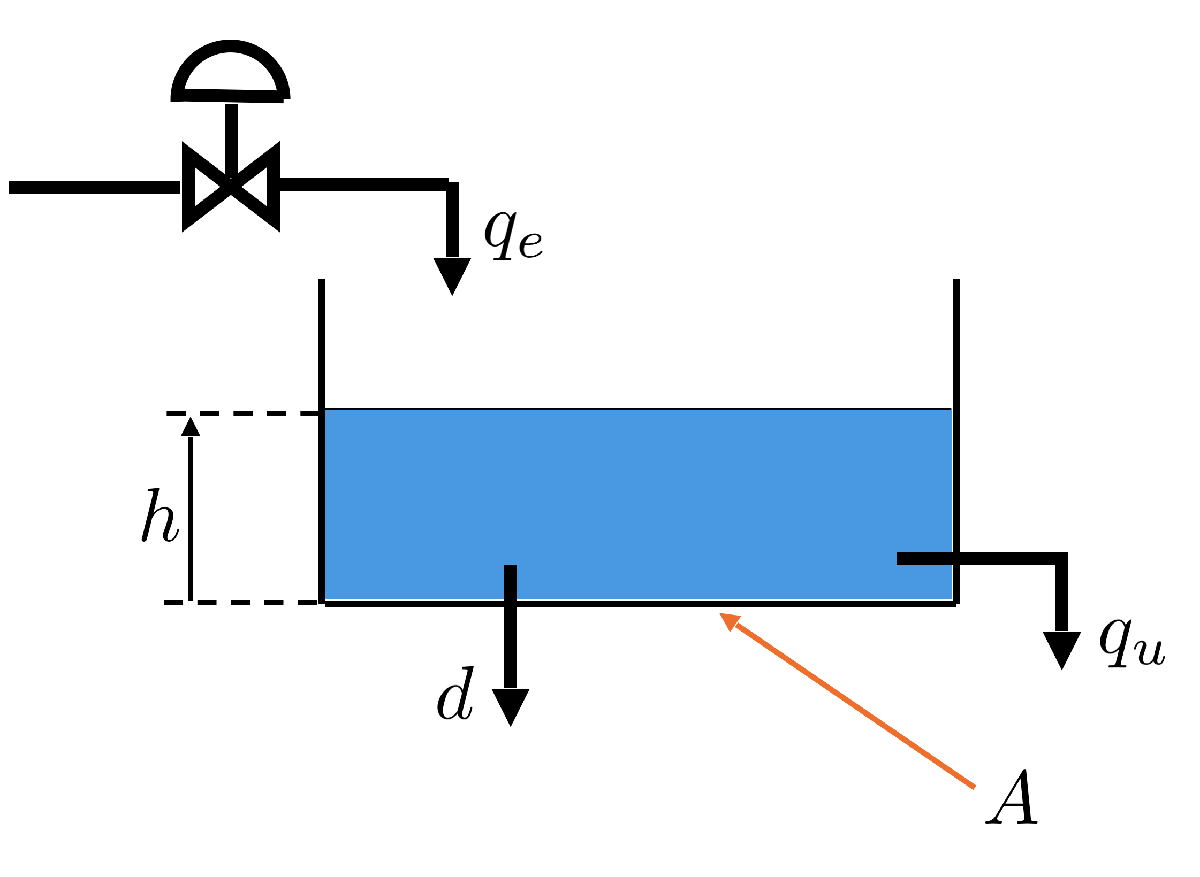

where

- control input: the input flow-rate $q_e$

- controlled output: the level of liquid in the tank $h$

- reference output: the constant desired level in the tank $w = h^{o}$

- out-flow rate:: $q_u = k \cdot h$

- disturbance: $d$

A real system that can be described by the model we are analysing is, for example, a paint mixing tank:

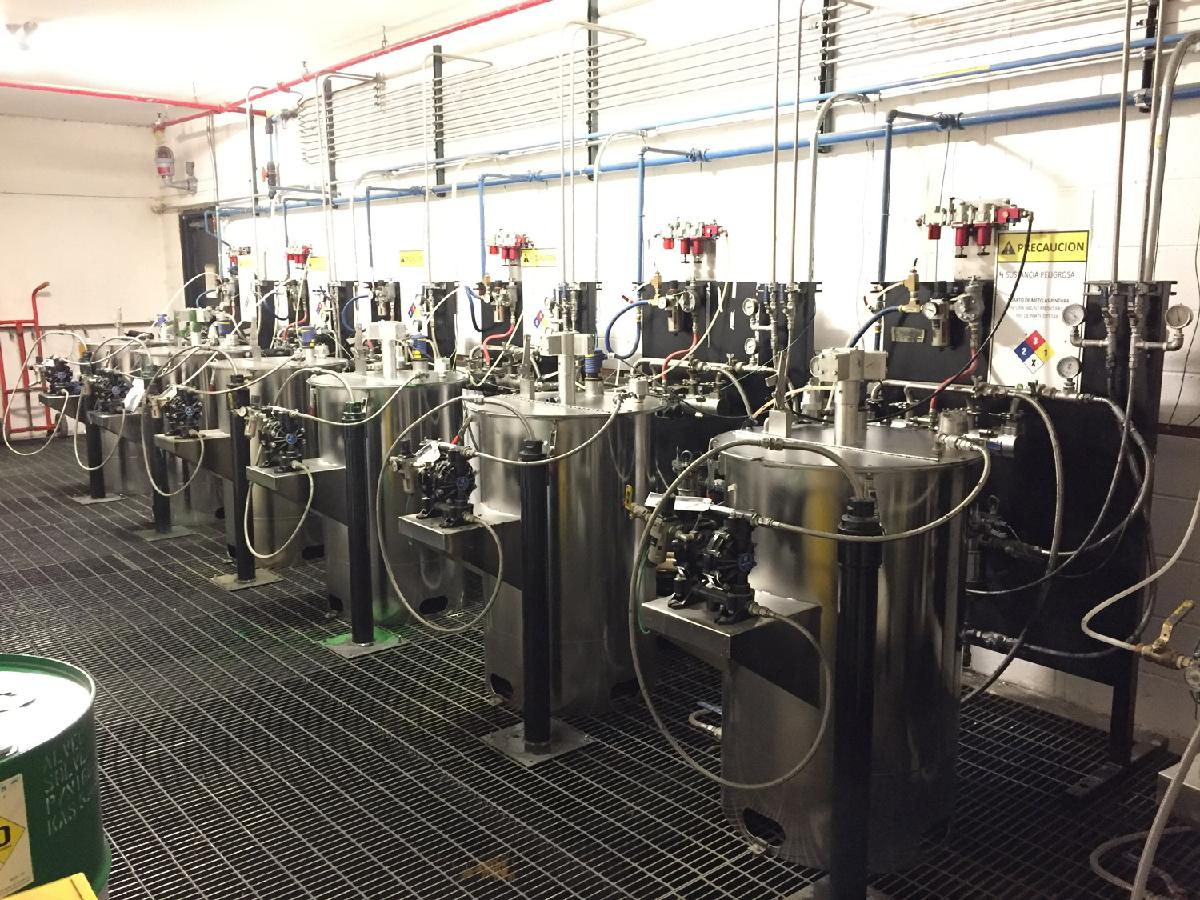

Paint mixing tanks (automotive industry).

### Dynamic Modelling - Different Scenarios: No Disturbance vs Step Disturbance

**First Scenario** - Usual assumptions:

- infinite-height of the tank (so we disregard the static nonlinearity due to the level saturation);

- incompressible liquid: in this way we may apply a simple volume conservation equation instead of the mass balance equation;

- **no disturbance** at all: $\forall t \; d(t)=0 \; $


$$\begin{array}{c}
\text{volume time variation } \;=\;  \text{input flow-rate }\;-\; \text{output flow-rate} \\
 \quad \Downarrow \quad \\
\left\{ \begin{array}{l}
A\,\dot{h}(t) = q_e(t)- q_u(t) -d(t) \\
d(t) = 0
\end{array} \right. \quad \Longrightarrow \quad \dot{h}(t) = \frac{1}{A}\,q_e(t) - \frac{k}{A}\,h(t)
\end{array}$$


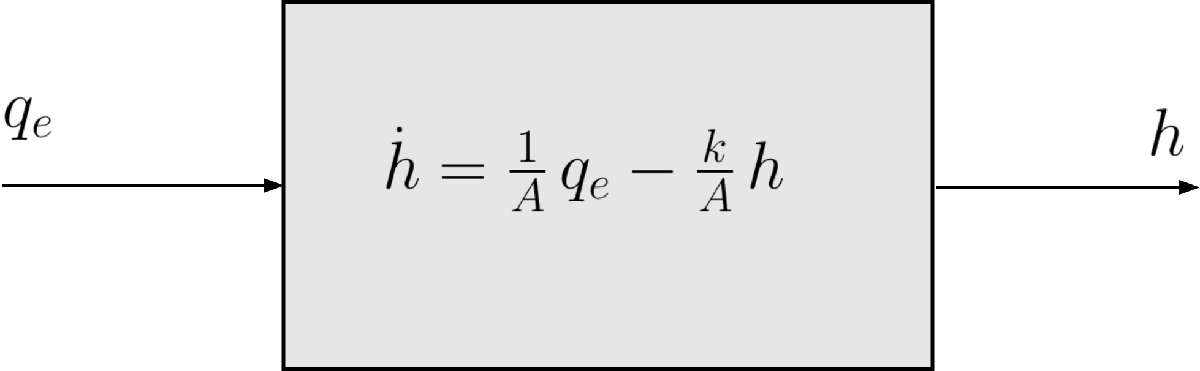

**Second Scenario** - Alternative assumptions:

- apply **a step disturbance** $d(t) = D \cdot \mathbf{1(t)}$, where $D \in \mathbb{R},\,D>0$ and $\mathbf{1(t)}$ is the Heaviside function


$$\mathbf{1(t)} := \left\{ \begin{array}{rcl}
1 &: & t \ge 0 \\ \\
0 &:& t<0
\end{array} \right.$$



$$\begin{array}{c}
\text{volume variation rate} \;=\;  \text{input flow-rate }\;-\; \text{output flow-rate} \\
 \quad \Downarrow \quad \\
\left\{ \begin{array}{l}
A\,\dot{h}(t) = q_e(t)- q_u(t) -d(t) \\
d(t) = D \cdot 1(t)
\end{array} \right. \quad \Longrightarrow \quad \dot{h}(t) = \frac{1}{A}\,q_e(t) - \frac{k}{A}\,h(t) - \frac{1}{A}\,D\cdot 1(t)
\end{array}$$


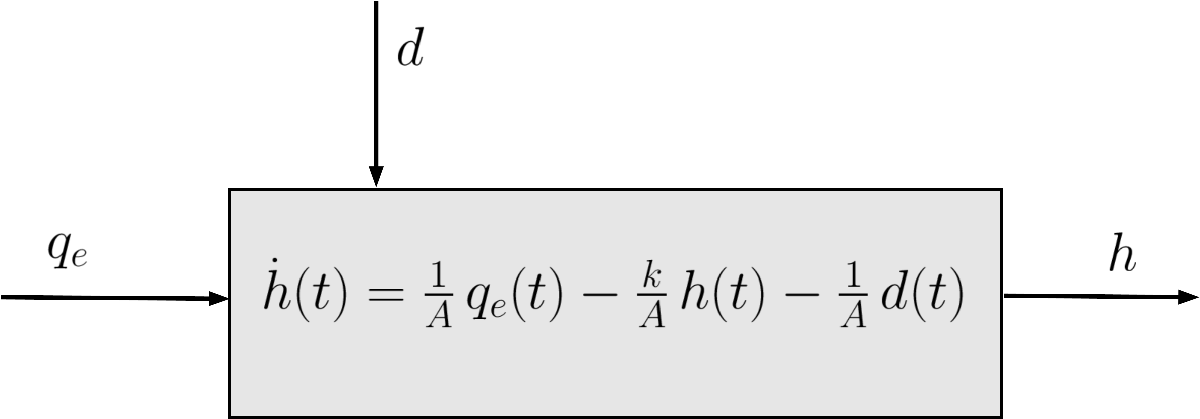

## Closed-Loop Control Strategy using a Proportional & Integral Controller : Performance Analysis 

We would like to control the liquid level $h$ by applying a **simple closed-loop control strategy**: the control action is the sum of a contribution **proportional** to the error between the desired set-point (the assigned liquid level set-point) and the actual value of the controlled variable (the liquid level in the tank) and a second contribution proportional to the **integral** (over time) of the error.


$$q_e = \mu\,\big[h^{o} - h(t) \big] + \varphi\,\int_{0}^{t}\,\big[h^{o}-h(\tau)\big]\,d\tau\;, \quad \mu,\,\varphi >0$$


#### **First Scenario**

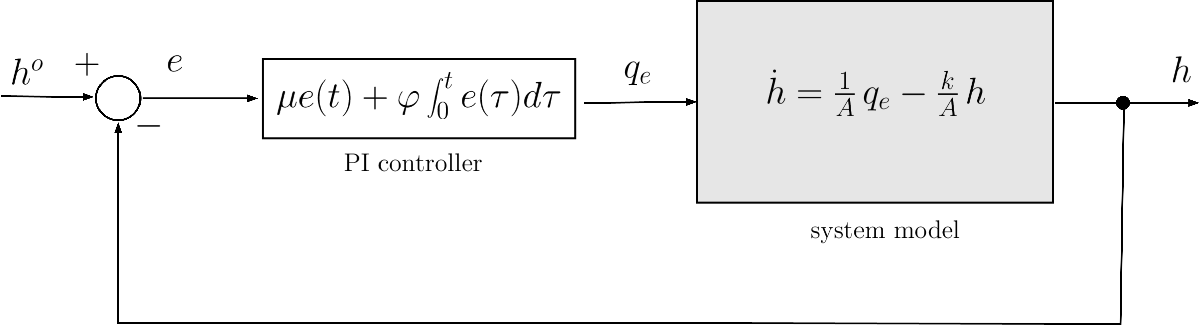

The system dynamics is now described by:


$$A \dot{h}(t)  = -k\,h(t) +\mu\,\big[h^{o} - h(t) \big] + \varphi\,\int_{0}^{t}\,\big[h^{o}-h(\tau)\big]\,d\tau$$


with initial conditions $h(0)$ and $\dot{h}(0)$.

#### **Second Scenario**

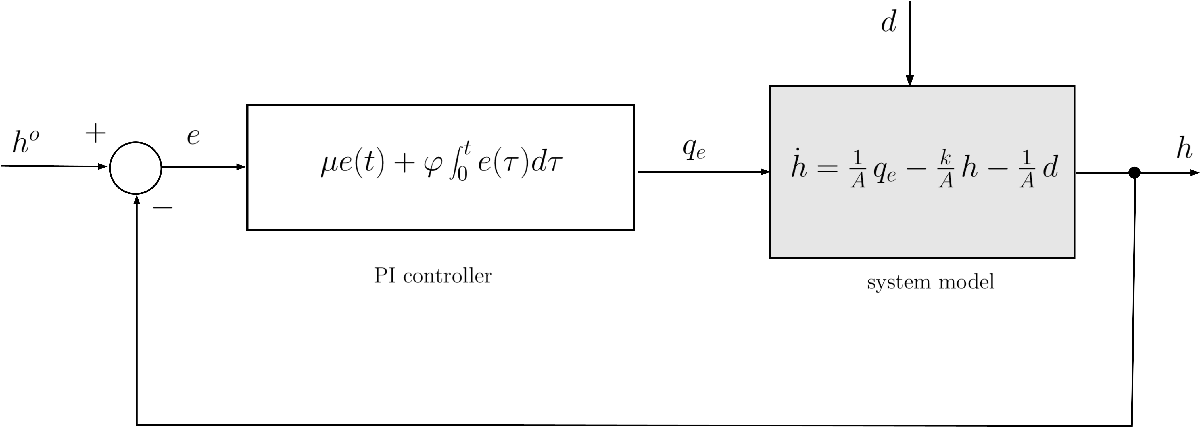

The system dynamics is now described by:


$$A \dot{h}(t)  = -k\,h(t) +\mu\,\big[h^{o} - h(t) \big] + \varphi\,\int_{0}^{t}\,\big[h^{o}-h(\tau)\big]\,d\tau -D\cdot 1(t)$$


with initial conditions $h(0)$ and $\dot{h}(0)$.

#### Performance Analysis

- How does the system behave when the initial conditions change? 

- Does the dynamic behaviour of the system depend either on the system's parameters and on the controller's parameter $\mu$ , or only on the system's parameters $A,\,k\,$?

- Using the closed-loop P control strategy are we able to impose a desired dynamic behaviour to the system?

Let's analyse the performance of the proposed control strategy, implementing the model and simulating its behaviour in different scenarios.

### The Dynamic Model  & the Control Strategy in Matlab

The nominal set of parameters' values is as follows:


$$\begin{array}{rclcrcl}
A&=& 12.34\,\text{m}^2 & \quad & h&=& 0.89 \, \text{m}^2\text{/s} 
\end{array}$$


% --------------- feedback control using a PI regulator -------------------
%
% The current script allows to simulate the feedback control of the tank
% system using a simple PI controller, as described in Part1 of the course
% material. 
%
% To perform the simulation, the script uses the Simulink model named
% "tank_model_PI.slx"
% -----------------------------------------------------------------------
clear % let's clean the Matlab workspace
close all
clc

### Performance Analysis 

- How does the system behave when the initial conditions change? 

- Does the dynamic behaviour of the system depend either on the system's parameters and on the controller's parameters $\mu,\, \varphi$ or only on the system's parameters $A,\,k\,$?

- Using the closed-loop PI control strategy are we able to impose a desired dynamic behaviour to the system?

To answer these questions, try changing the initial conditions, or the system parameters (or all of these) and simulate the behaviour of the system.

Jump to the Simulation Results section.

#### Initial Conditions

Modify the initial liquid level in the tank $h(0)$ and analyse the result

 

h_init = 3.044; % [m]
% initial level of fluid into the tank


- Jump to the section "The Simulation Results: the Behaviour of the Controlled System - First Scenario: No Disturbance"

- Jump to the section: "The Simulation Results: the Behaviour of the Controlled System - Second Scenario: Step Disturbance"

#### Setting the Proportional & Integral Gains 

Theey are the controller parameters: setting the **proportional gain **$\mu$ and the **integral** **gain** $\varphi$ we are able to modify the controlled system behaviour.

- What would happen if we choose a very small positive value for $\mu$? What if we increase the gain?

- Would the performance of the control system remain the same? Would it improve? Would it get worse?

- Experiment with what happens if you select a different value. 

- For example, what if you use a value 10 times smaller or 10  times larger for $\mu$ and/or $\varphi$?

- Does the performance change? 

- Does the steady-state error change or remain the same?

- What happens if $\mu$ and $\varphi$ have similar values? What if $\varphi$ has a higher value than $\mu$?

muP = 1073;
% Modify the P gain value and simulate. What happens to the
% controlled system performance?

phiI = 5.04; 
% Modify the I gain value and simulate. What happens to the
% controlled system performance?
      
 

- Jump to the section "The Simulation Results: the Behaviour of the Controlled System - First Scenario: No Disturbance"

- Jump to the section: "The Simulation Results: the Behaviour of the Controlled System - Second Scenario: Step Disturbance"

#### System Parameters 

The nominal set of parameters' values is as follows:


$$\begin{array}{rclcrcl}
A&=& 12.34\,\text{m}^2 & \quad & k&=& 0.89 \, \text{m}^2\text{/s} 
\end{array}$$


What if you modify the system's parameters?

A = 12.34;   % [m^2] area of the tank section
k = 0.89;    % [m^2/s]  k is the coefficient of the linear law for 
                             % calculating the outlet flow rate q_out as a function of the 
                             % liquid level h in the tank
                             %
                             % q_out = k * h
                             %
  


- Jump to the section "The Simulation Results: the Behaviour of the Controlled System - First Scenario: No Disturbance"

- Jump to the section: "The Simulation Results: the Behaviour of the Controlled System - Second Scenario: Step Disturbance"

In fact, given the integral-differential equation 


$$A \dot{h} + k\,h = \mu\,\big[h^{o} - h(t) \big] + \varphi\,\int_{0}^{t}\,\big[h^{o}-h(\tau)\big]\,d\tau$$


the associated polynomial algebraic equation is 


$$A\, \lambda+ \left(k +\mu\right) +\varphi\, \lambda^{-1}= 0 \quad \Longleftrightarrow \quad A\, \lambda^2+\left(k +\mu\right)\lambda +\varphi=0\,,\; \lambda \ne0$$


and its roots are

roots_CharPolyODE =roots([A (k+muP) phiI])

roots_CharPolyODE =   -87.0204
   -0.0047


**Note**: the system behaviour depens on the system's parameters ( $A,\,k\,$) and on the controller gains $\mu,\,\varphi$. 

- What happens if you increase the controller's gain $\mu$ and/or $\varphi$?

#### Set Point

Assign the desired liquid level. 

- Can the current control law guarantee that the desired level is reached?

 

% set point
h_0 = 6.7;    % [m] desired fluid level in the tank


- Jump to the section "The Simulation Results: the Behaviour of the Controlled System - First Scenario: No Disturbance"

- Jump to the section: "The Simulation Results: the Behaviour of the Controlled System - Second Scenario: Step Disturbance"

#### Simulation Time Interval

Set the duration of the simulation:

 

Tfinal = 1; % [s] simulation in the time internal [0 Tmax]

- Jump to the section "The Simulation Results: the Behaviour of the Controlled System - First Scenario: No Disturbance"

- Jump to the section: "The Simulation Results: the Behaviour of the Controlled System - Second Scenario: Step Disturbance"

### Solving an Ordinary Differential Equation in MATLAB - First Scenario - No Disturbance

We would solve the first-order Ordinary Differential Equation (ODE)


$$A \dot{h} + k\,h = \mu\,\big[h^{o} - h(t) \big] + \varphi\,\int_{0}^{t}\,\big[h^{o}-h(\tau)\big]\,d\tau \;, \qquad h(0) =\bar h \qquad (\star)$$


in MATLAB, numerically, using the command `ode`.  

For help on using the command `ode`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `ode` command allows us to solve [Initial Value Problems (IVPs)](https://www.youtube.com/watch?v=C3WKwB5gBqI) of the form


$$\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$$


where $y$ is a continuous function of the independent variable $t$ (i.e., the solution of the ODE we are looking for), and $p$ is a vector of parameters.

Thus, given the first-order ODE to solve, we must perform a single-step procedure to obtain the (numerical) ODE solution using the MATLAB command `ode`:

**One-Step Procedure**: Define the system of first-order ODEs with given initial conditions in MATLAB, using the command `ode`.

The original Eq. $(\star)$ is an integro-differential equation: we must transform it in a system of first-order ODEs, applying the following simple trick (substitution of variables)


$$\left\{ \begin{array}{l}
A \dot{h}(t) + k\,h(t) = \mu\,\big[h^{o}(t) - h(t) \big] + \varphi\,\int_{0}^{t}\,\big[h^{o}(\tau)-h(\tau)\big]\,d\tau \\
y_1(t) := h(t) \\ \\
y_2(t) := \int_{0}^{t}\,\big[h^{o}-h(\tau)\big]\,d\tau \quad \Longrightarrow \quad \dot{y}_2(t) = e(t) \\
\end{array} \right. \qquad \Longrightarrow \quad
\left\{ \begin{array}{rcl}
\dot{y}_1(t) &=& -\frac{\mu+k}{A}\,y_1(t) + \frac{\mu}{A}\, h^{o}(t)+\frac{\varphi}{A}\,y_2(t) \\
\dot{y}_2(t) &=& -\mu\,y_1(t) + \mu\, h^{o}(t)
\end{array} \right.$$


Thus


$$\left\{ \begin{array}{rcl}
\dot{y}_1(t) &=& -\frac{\mu+k}{A}\,y_1(t) + \frac{\mu}{A}\, h^{o}(t)+\frac{\varphi}{A}\,y_2(t) \\
\dot{y}_2(t) &=& -\mu\,y_1(t) + \mu\, h^{o}(t) \\ \\
y_1(0) &= & \bar h \\
y_2(0) &=& 0
\end{array} \right.  \qquad \Longrightarrow \qquad 
 \begin{array}{rcl}
y_1(t) &=& ?
\end{array} $$


% Note: using the default configuration for the current live script, all
% the MATLAB code is hidden, so you cannot see this portion of code, unless
% you modify the live script general visualisation properties.
%
F_ODE = ode;                              % let's initialise an ODE object
F_ODE.Parameters   = [A, k, h_0, muP, phiI, 0]; % the parameters of the differential equation

% NOTE: We also pass the amplitude D of the step-like disturbance d(t)
% [actually D=0 in this scenario] as a parameter. 
% For practicality, we prefer to manage only one ODE, which can cope 
% with both scenarios, just configuring the parameters appropriately. 

F_ODE.InitialValue = [h_init, 0];         % the initial conditions
F_ODE.InitialTime = 0;                    % the initial time instant of the solution, where 
                                          % the initial conditions are applied
F_ODE.ODEFcn = @TankPIFeedbackODE;  % TankPIFeedbackODE is the MATLAB function describing the ODE, 
                                    % we would like to solve. 
                                    % The code of TankPIFeedbackODE is at the end
                                    % of this live script.

#### Simulation of the Controlled System - Solving the ODE - First Scenario: No Disturbance

Given the MATLAB description of the IVP we would solve, let's determine a numeric solution by applying the MATLAB command `solve`.

For help on using the command `solve`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `solve` command computes the solution of the considered IVP `F` in the time interval `[t0, tf]`, returning the solution `S` at each time step chosen by the solver: 

% Note: using the default configuration for the current live script, all
% the MATLAB code is hidden, so you cannot see this portion of code, unless
% you modify the live script general visualisation properties.
%
t0 = 0; % the initial time instant
% tf already assigned
S  = solve(F_ODE, t0, Tfinal); % solve the IPV described by F_ODE 
                           % in the time interval [t0, tf]

tank_level = S.Solution(1,:); % the result of the IPv
t_stamps   = S.Time;          % time instants corresponding to the solution samples 


#### The Simulation Results: the Behaviour of the Controlled System - First Scenario: No Disturbance

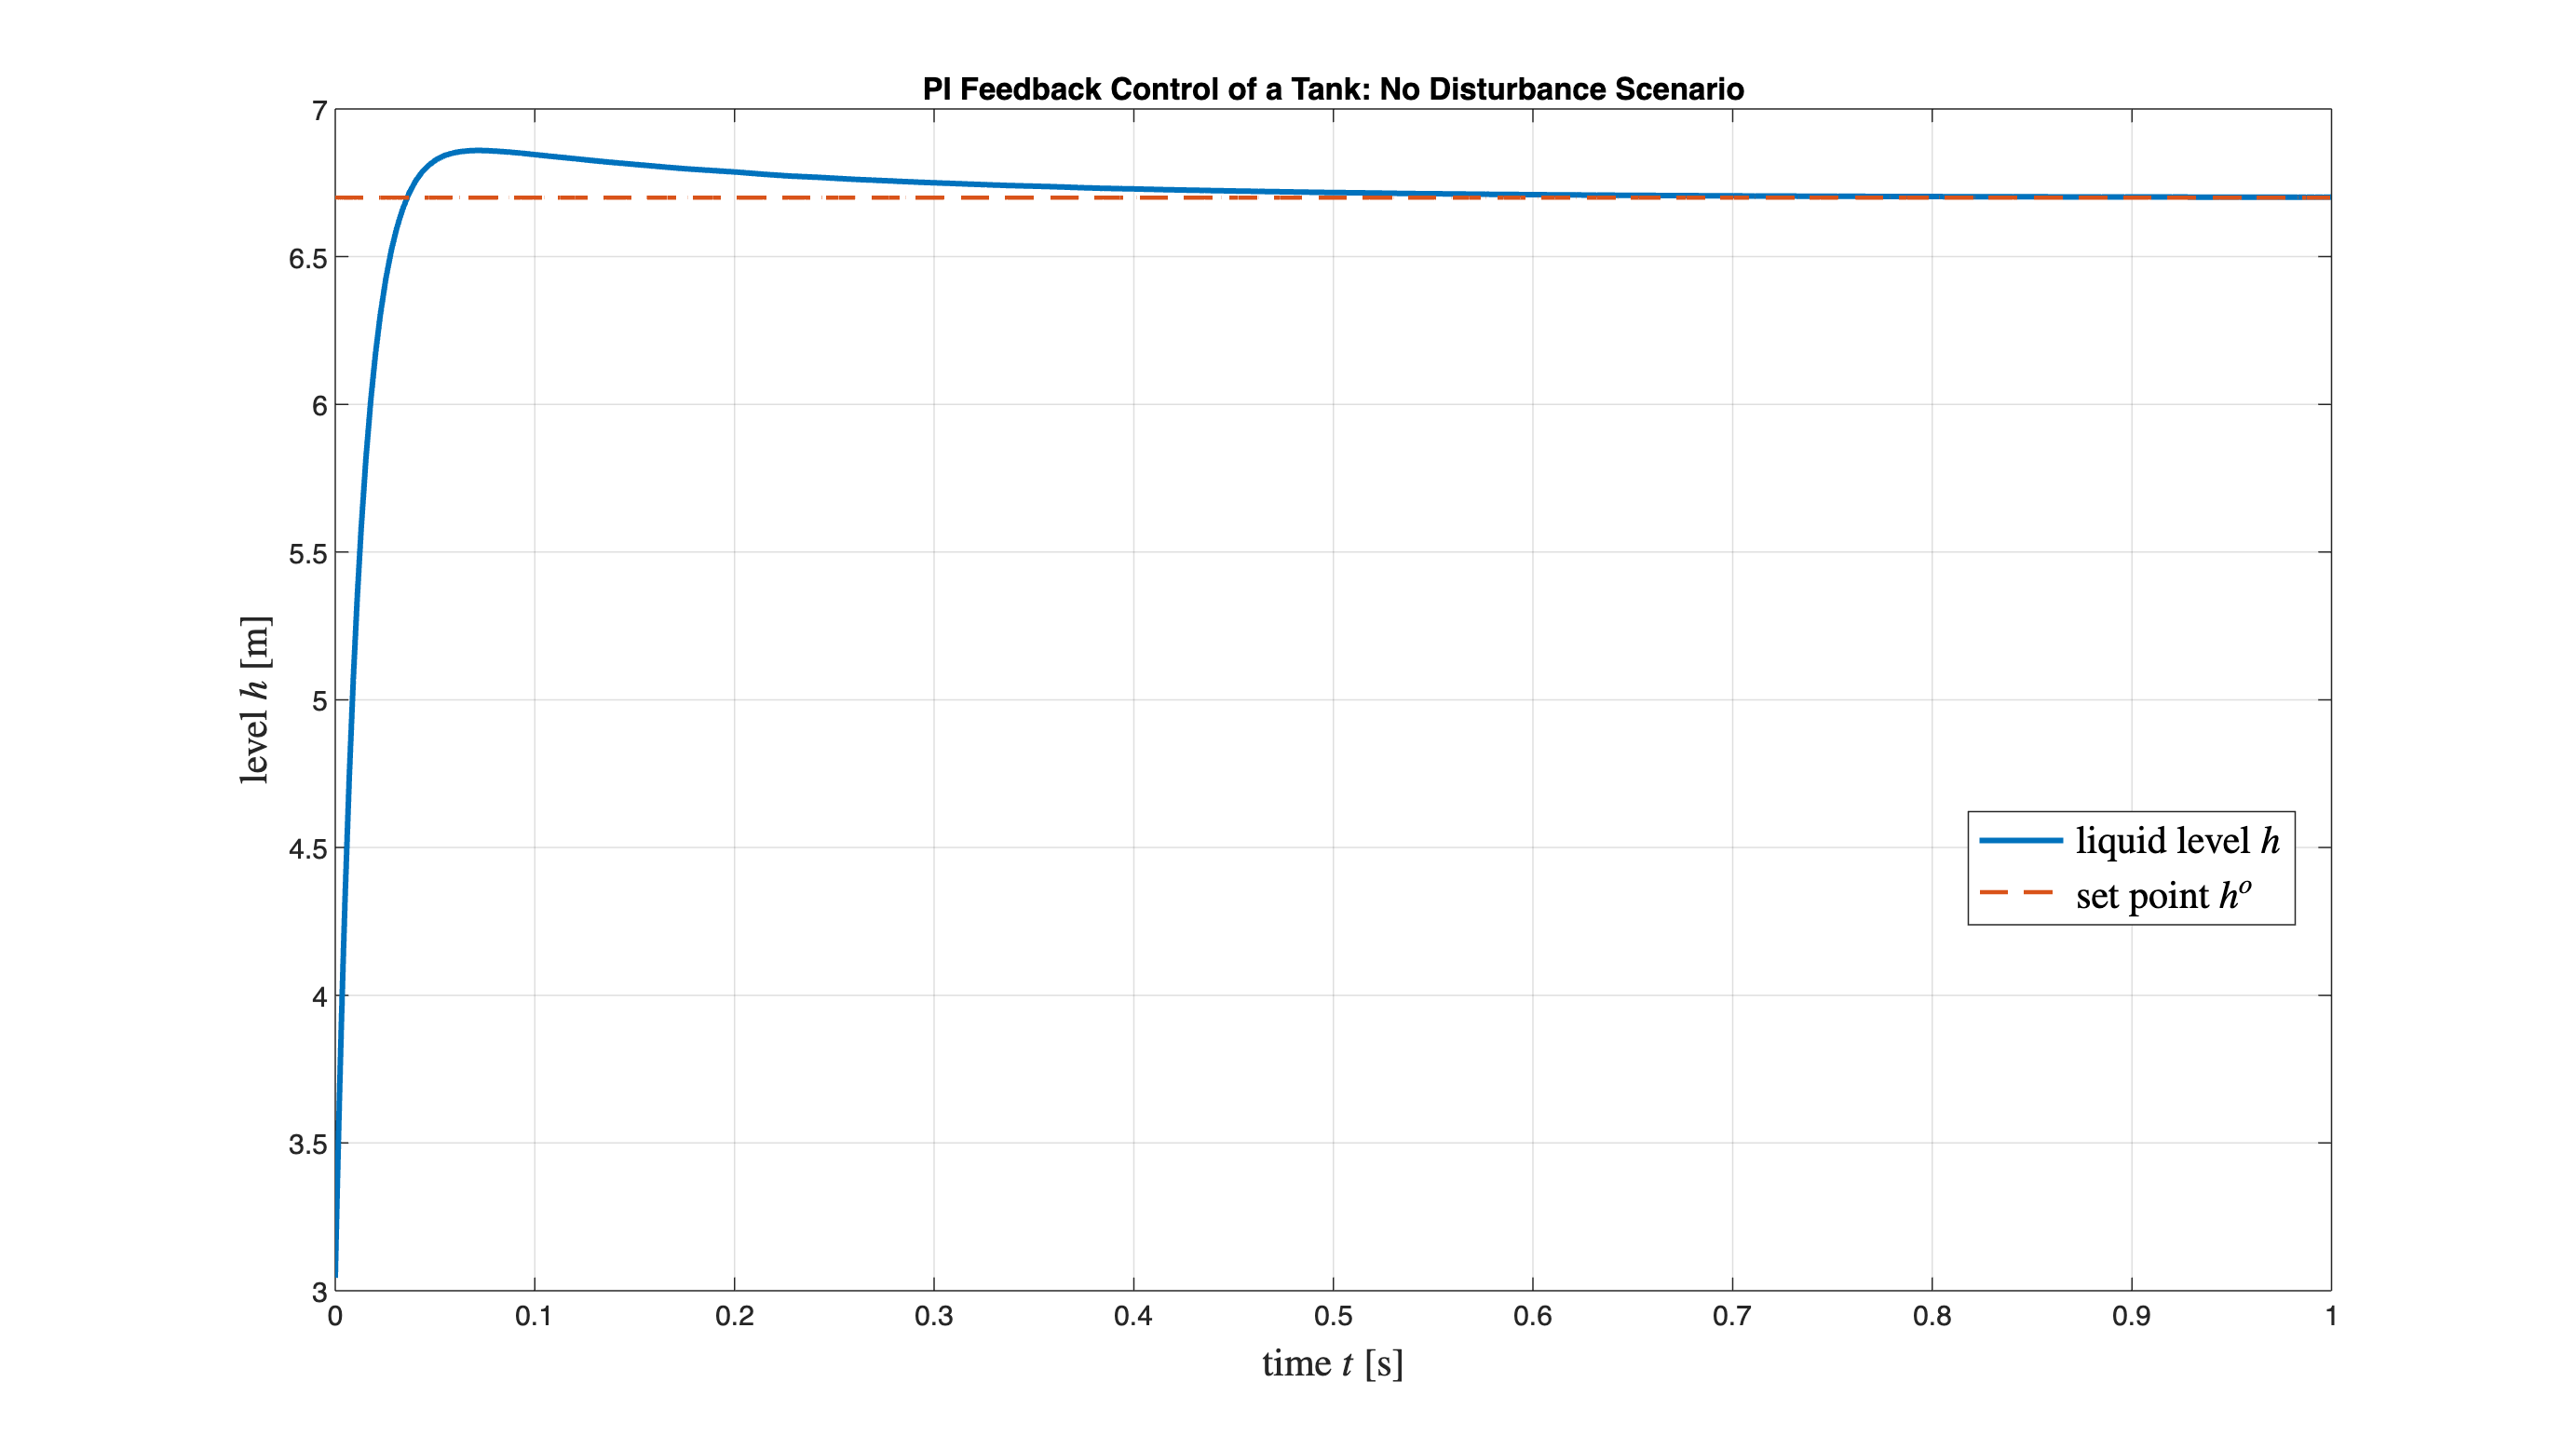

% Note: using the default configuration for the current live script, all
% the MATLAB code is hidden, so you cannot see this portion of code, unless
% you modify the live script general visualisation properties.
%
figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.95]);

plot(t_stamps, tank_level, 'LineWidth',2); % cart position vs time
hold on; % let's add another plot: the set-point
plot(t_stamps, h_0*ones(size(t_stamps)),'LineStyle','--','LineWidth',1.5); 
xlim([min(t_stamps), max(t_stamps)]);

xlabel('time $t$ [s]', 'FontSize', 14, 'Interpreter','latex'); % labels on the plot axes
ylabel('level $h$ [m]', 'FontSize', 14, 'Interpreter','latex'); 

grid on; % let's insert a grid in the figure
title('PI Feedback Control of a Tank: No Disturbance Scenario');
legend('liquid level $h$', 'set point $h^{o}$', ...
        'Interpreter', 'latex', 'FontSize', 14, 'Location', 'best' );% adding a legend

- Modify the simulation time interval.

- Assign the set point.

- Modify the system parameters.

- Set the controller gains.

- Assign the initial conditions.

### Solving an Ordinary Differential Equation in MATLAB - Second Scenario - Step Disturbance

#### Setting the Disturbance

Let's assign the amplitude of the step disturbance;

% disturbance d amplitude
    
D_dV = 3.9; % [m^3/s] disturbance flow rate. ACTIVE DISTURBANCE SCENARIO


 


- Jump to the section: "The Simulation Results: the Behaviour of the Controlled System - Second Scenario: Step Disturbance"

We would solve the first-order Ordinary Differential Equation (ODE)


$$A\, \dot{h} + k \,h +D\cdot 1(t)= \mu\,\big[h^{o} - h(t) \big] + \varphi\,\int_{0}^{t}\,\big[h^{o}-h(\tau)\big]\,d\tau\;, \qquad h(0) =\bar h,\quad D > 0 \qquad (\circ)$$


in MATLAB, numerically, using the command `ode`.  

For help on using the command `ode`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `ode` command allows us to solve [Initial Value Problems (IVPs)](https://www.youtube.com/watch?v=C3WKwB5gBqI) of the form


$$\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$$


where $y$ is a continuous function of the independent variable $t$ (i.e., the solution of the ODE we are looking for), and $p$ is a vector of parameters.

Thus, given the first-order ODE to solve, we must perform a single-step procedure to obtain the (numerical) ODE solution using the MATLAB command `ode`:

**One-Step Procedure**: Define the system of first-order ODEs with given initial conditions in MATLAB, using the command `ode`.

The original Eq. $(\circ)$ is an integro-differential equation: we must transform it in a system of first-order ODEs, applying the following simple trick (substitution of variables)


$$\left\{ \begin{array}{l}
A \dot{h}(t) + k\,h(t) +D\cdot 1(t)= \mu\,\big[h^{o}(t) - h(t) \big] + \varphi\,\int_{0}^{t}\,\big[h^{o}(\tau)-h(\tau)\big]\,d\tau \\
y_1(t) := h(t) \\ \\
y_2(t) := \int_{0}^{t}\,\big[h^{o}-h(\tau)\big]\,d\tau \quad \Longrightarrow \quad \dot{y}_2(t) = e(t) \\
\end{array} \right. \qquad \Longrightarrow \quad
\left\{ \begin{array}{rcl}
\dot{y}_1(t) &=& -\frac{\mu+k}{A}\,y_1(t) + \frac{\mu}{A}\, h^{o}(t)+\frac{\varphi}{A}\,y_2(t) -D \cdot 1(t) \\
\dot{y}_2(t) &=& -\mu\,y_1(t) + \mu\, h^{o}(t)
\end{array} \right.$$


Thus


$$\left\{ \begin{array}{rcl}
\dot{y}_1(t) &=& -\frac{\mu+k}{A}\,y_1(t) + \frac{\mu}{A}\, h^{o}(t)+\frac{\varphi}{A}\,y_2(t) -D \cdot 1(t)\\
\dot{y}_2(t) &=& -\mu\,y_1(t) + \mu\, h^{o}(t) \\ \\
y_1(0) &= & \bar h \\
y_2(0) &=& 0
\end{array} \right.  \qquad \Longrightarrow \qquad 
 \begin{array}{rcl}
y_1(t) &=& ?
\end{array} $$


% Note: using the default configuration for the current live script, all
% the MATLAB code is hidden, so you cannot see this portion of code, unless
% you modify the live script general visualisation properties.
%
F_ODE_d = ode;                              % let's initialise an ODE object
F_ODE_d.Parameters   = [A, k, h_0, muP, phiI, D_dV]; % the parameters of the differential equation

% NOTE: We also pass the amplitude D of the step-like disturbance d(t)
% as a parameter. 
% For practicality, we prefer to manage only one ODE, which can cope 
% with both scenarios, just configuring the parameters appropriately. 

F_ODE_d.InitialValue = [h_init, 0];         % the initial conditions
F_ODE_d.InitialTime = 0;                    % the initial time instant of the solution, where 
                                          % the initial conditions are applied
F_ODE_d.ODEFcn = @TankPIFeedbackODE;   % TankPFeedbackODE is the MATLAB function describing the ODE, 
                                    % we would like to solve. 
                                    % The code of TankPIFeedbackODE is at the end
                                    % of this live script.

#### Simulation of the Controlled System - Solving the ODE - Second Scenario: Step Disturbance

Given the MATLAB description of the IVP we would solve, let's determine a numeric solution by applying the MATLAB command `solve`.

% Note: using the default configuration for the current live script, all
% the MATLAB code is hidden, so you cannot see this portion of code, unless
% you modify the live script general visualisation properties.
%
t0 = 0; % the initial time instant
% tf already assigned
Sd  = solve(F_ODE_d, t0, Tfinal); % solve the IPV described by F_ODE 
                           % in the time interval [t0, tf]

tank_levelD = Sd.Solution(1,:); % the result of the IPv
t_stamps   = Sd.Time;          % time instants corresponding to the solution samples 


#### The Simulation Results: the Behaviour of the Controlled System - Second Scenario: Step Disturbance

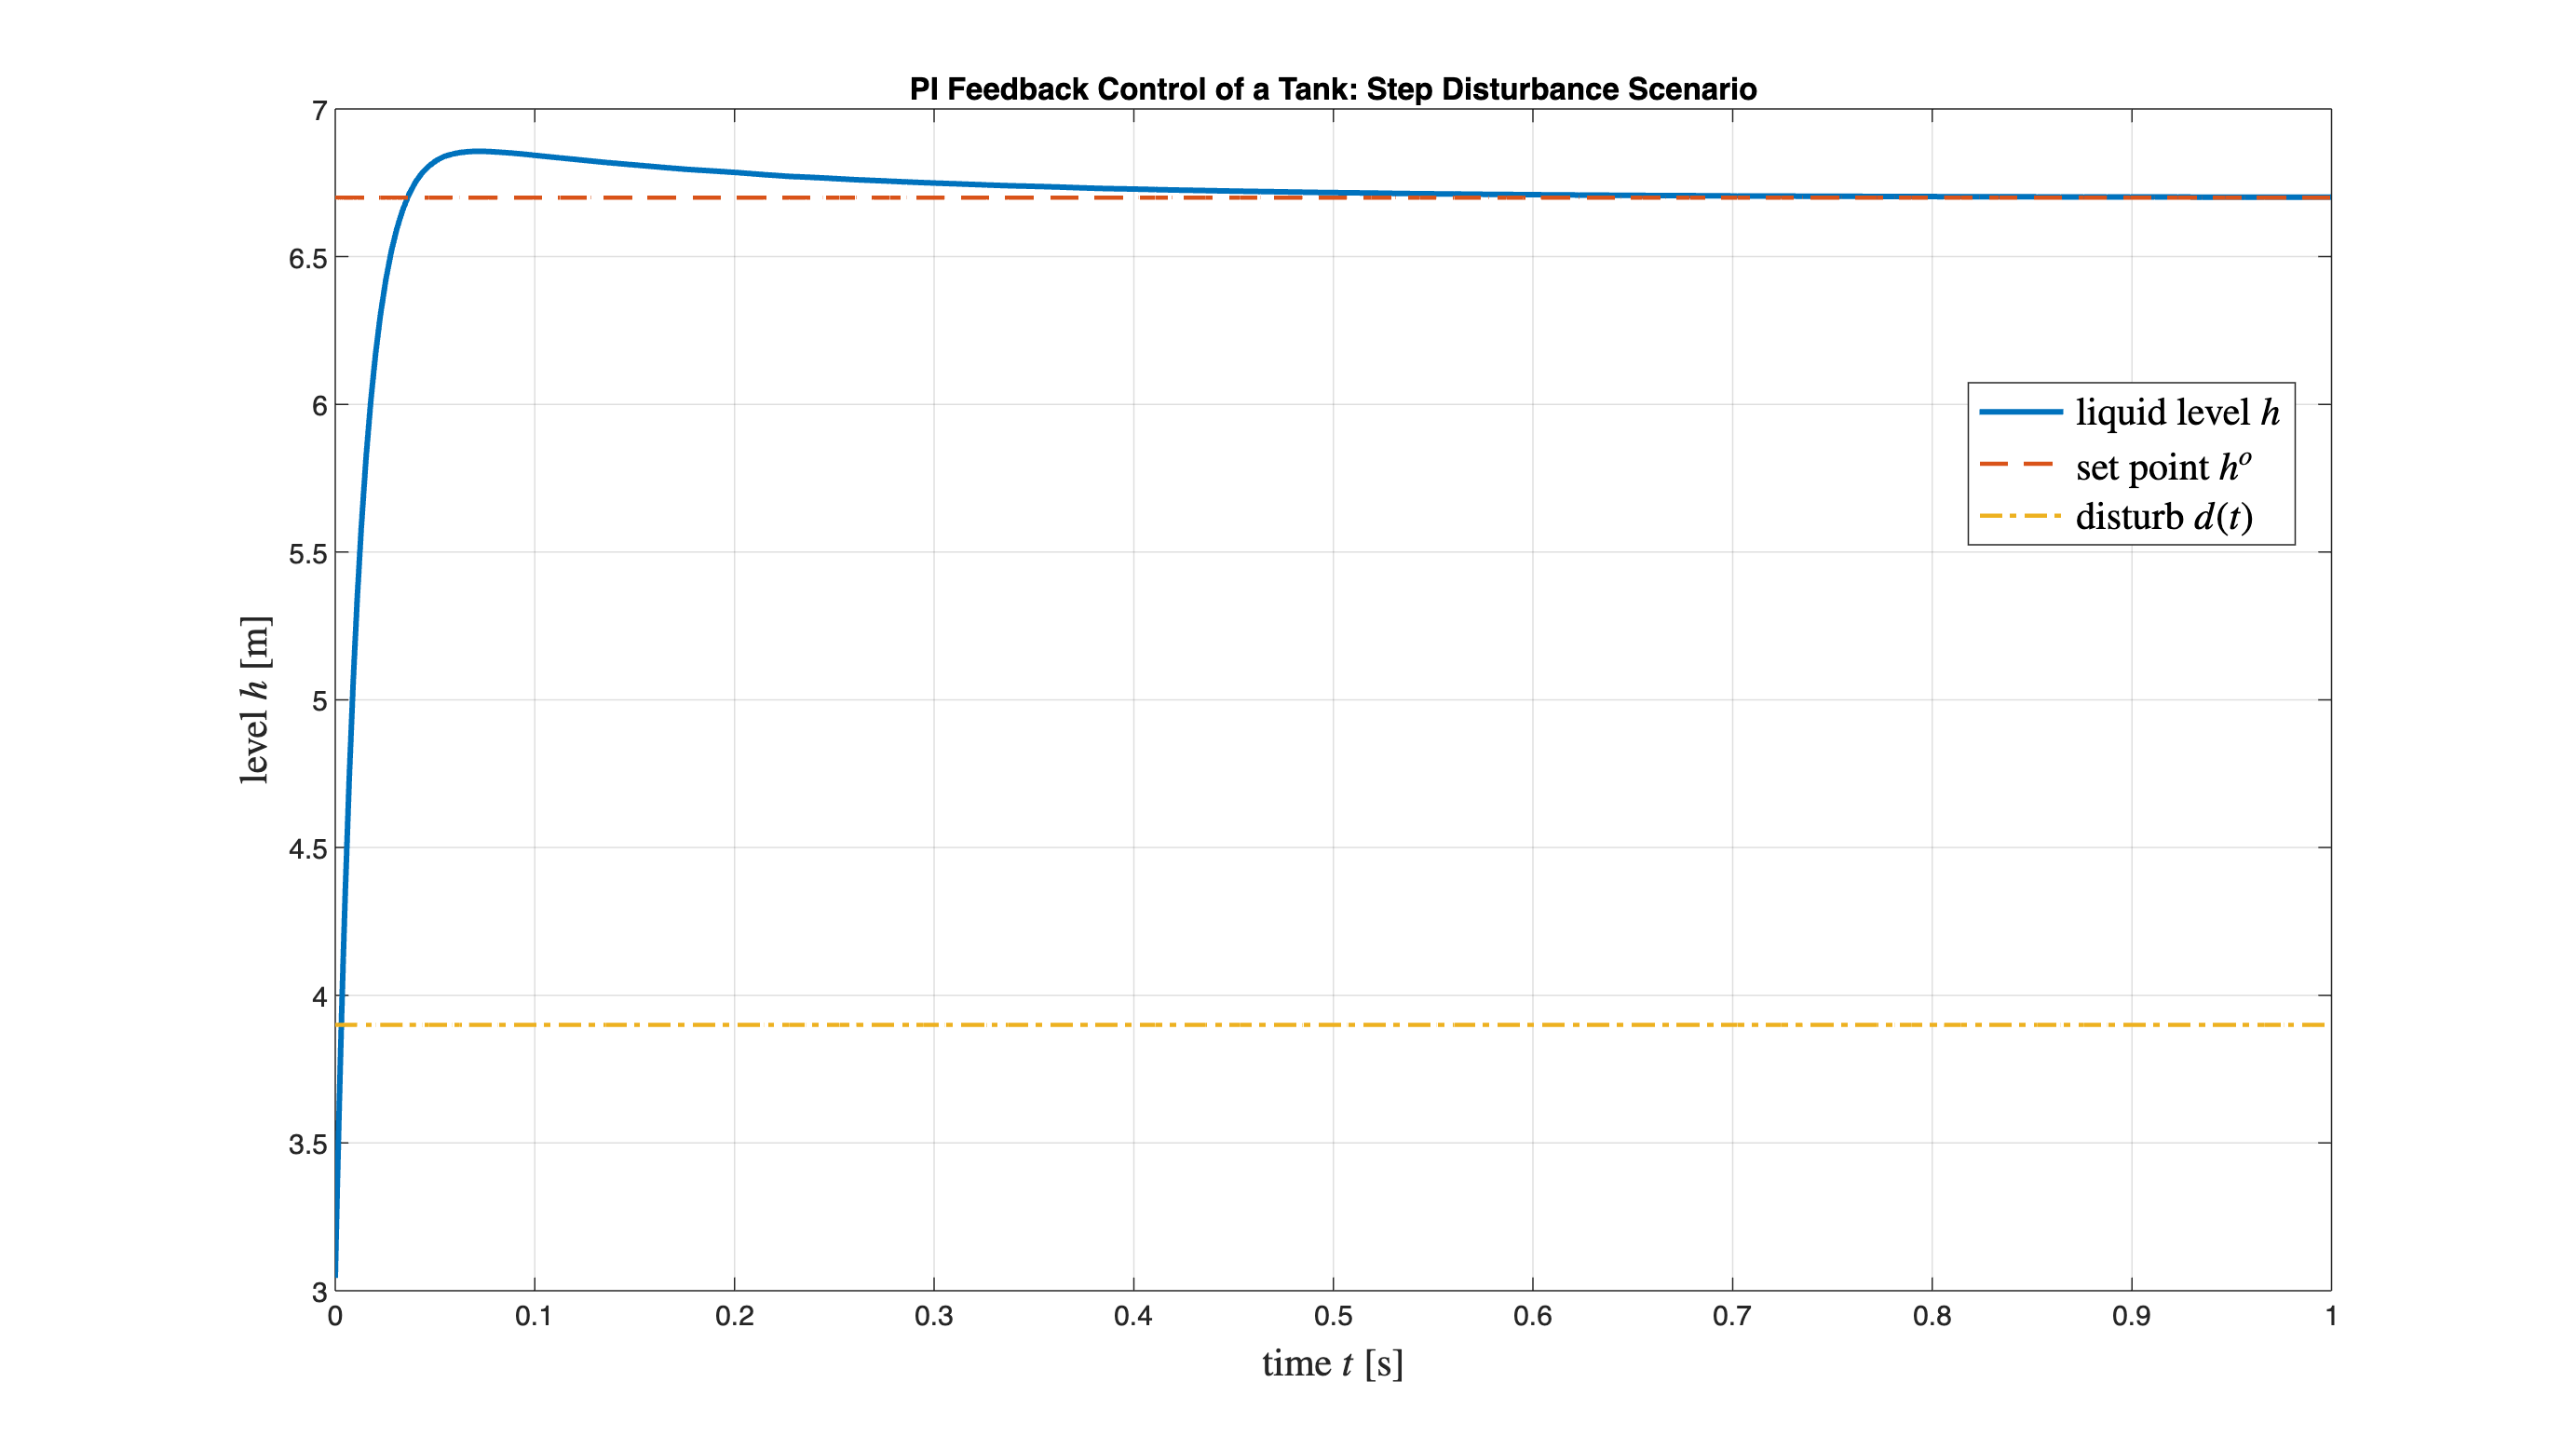

figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.95]);

plot(t_stamps, tank_levelD, 'LineWidth',2); % cart position vs time
hold on; % let's add another plot: the set-point
plot(t_stamps, h_0*ones(size(t_stamps)),'LineStyle','--','LineWidth',1.5); 
plot(t_stamps, D_dV*ones(size(t_stamps)),'LineStyle','-.','LineWidth',1.5); 
xlim([min(t_stamps), max(t_stamps)]);

xlabel('time $t$ [s]', 'FontSize', 14, 'Interpreter','latex'); % labels on the plot axes
ylabel('level $h$ [m]', 'FontSize', 14, 'Interpreter','latex'); 

grid on; % let's insert a grid in the figure
title('PI Feedback Control of a Tank: Step Disturbance Scenario');
legend('liquid level $h$', 'set point $h^{o}$', 'disturb $d(t)$',...
        'Interpreter', 'latex', 'FontSize', 14, 'Location', 'best' );% adding a legend

- Modify the simulation time interval.

- Assign the set point.

- Modify the system parameters.

- Set the controller gains.

- Assign the initial conditions.

## The ODE as MATLAB Function

Let's define as a **MATLAB** **function** the first-order ODE corresponding to


$$\left\{ \begin{array}{rcl}
\dot{y}_1(t) &=& -\frac{\mu+k}{A}\,y_1(t) + \frac{\mu}{A}\, h^{o}(t)+\frac{\varphi}{A}\,y_2(t) -\frac{1}{A}\,D \cdot 1(t) \\
\dot{y}_2(t) &=& -\mu\,y_1(t) + \mu\, h^{o}(t) \\ \\
y_1(0) &= & \bar h \\
y_2(0) &=& 0
\end{array} \right. $$


The MATLAB function must provide the first derivative $\dot{y}_1(t)$, given the values of the function $y_1$ at the current time instant $t$ and the parameters'values.

% Note: using the default configuration for the current live script, all
% the MATLAB code is hidden, so you cannot see this portion of code, unless
% you modify the live script general visualisation properties.
%
function dydt = TankPIFeedbackODE(t, y, p)

    % retrieving the parameters
    A_val   = p(1);
    k_val   = p(2);
    h0_val  = p(3);
    muP_val = p(4);
    phiI_val = p(5);
    D_val   = p(6);

    kMuA = (k_val+muP_val)/A_val;
    D_A  = D_val/A_val;
    U    = (muP_val/A_val)*h0_val;
    PhiA = phiI_val/A_val;

    dydt = [-kMuA*y(1)+U+PhiA*y(2)-D_A;...
            -muP_val*y(1)+muP_val*h0_val];

end % function